# PODSTAWY PROGRAMOWANIA W JĘZYKU MATLAB

## Skrypty

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Rigth"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

Zazwyczaj poszczególnych komend nie zapisujemy bezpośrednio w konsoli, ale korzystamy z plików zawierających zbiory komend - programy. W MATLAB mamy kilka głównych kategorii tego rodzaju plików, a podstawową z nich są skrypty. To właśnie ze skryptów będziesz głównie korzystał w trakcie zajęć laboratoryjnych.

Skrypt jest to zapis komend MATLAB w postaci tekstowej, które będą podawane do interpretatora poleceń w kolejności w jakiej występują w pliku. 

**Aby dany plik był interpretowany jako skrypt musi być zapisany jako m-plik.**

**Eksperyment:**

Stwórz nowy plik tekstowy (m-plik) poprzez kliknięcie opcji:

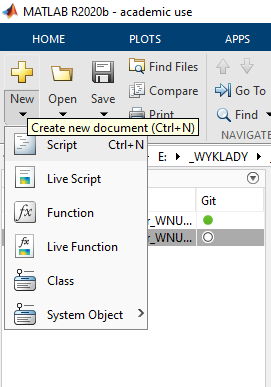

i zapisanie go z rozszerzeniem .m np. jako "test.m". Skopiuj i wklej do niego następujący kod:

clear all;
close all;

display('Dzialanie skryptu dobieglo konca');

Dzialanie skryptu dobieglo konca


fprintf('Dzialanie skryptu dobieglo konca');

Dzialanie skryptu dobieglo konca

Następnie zapisz kopię tego pliku bez żadnego rozszerzenia np. test.

Zwróć uwagę jak wygląda interfejs użytkownika w przypadku edycji i pracy z plikiem test.m i test. 

Dla test.m widoczne jest okno edytora skryptu:

                                  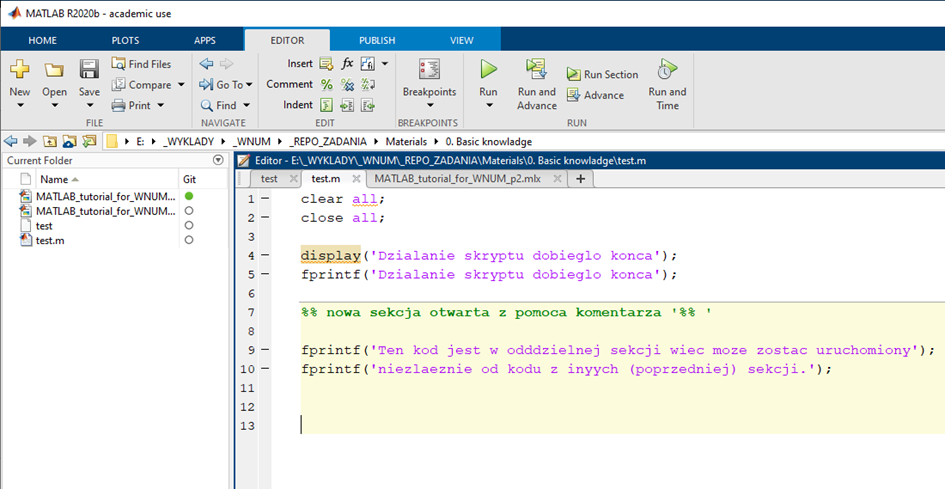

A dla pliku test (bez rozszerzenia) okno to nie ma panelu 'RUN', ponadto MATLAB nie koloruje składni w edytorze tekstu. To dlatego, że plik bez rozszerzenia nie jest traktowany przez MATLABA jako plik interpretowalny (skrypt) i np. nie może zostać uruchomiony.

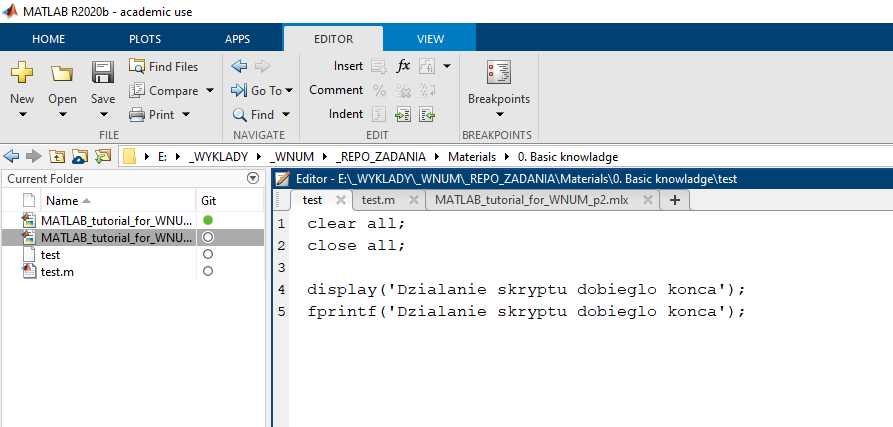

Przyjrzyjmy się jeszcze na chwilkę budowie okna edytora dla m-pliku. Zwrócić uwagę na następujące elementy interfejsu użytkownika, z których część jest widoczna tylko przy edycji pliku wykonywalnego (m-pliku):

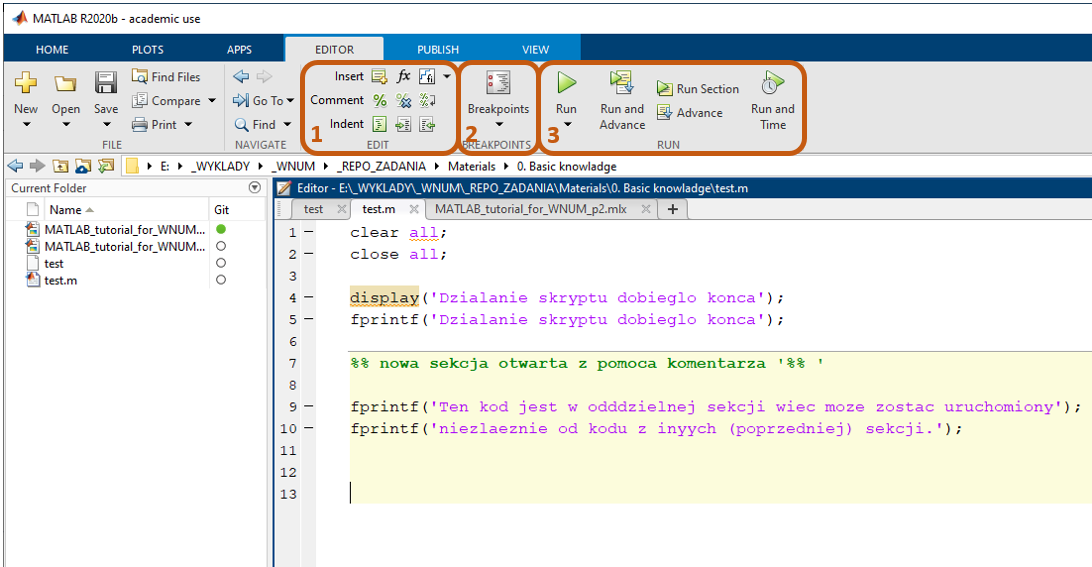

Widzimy tutaj trzy panele kontrolek, które mogą być istotne z punktu widzenie uruchamiania skryptu:

Panel 'EDIT'

- Kontrolki z tego panelu pozwalają na edycję skryptu. Można np. budować skrypt korzystając z kreatora w formie graficznej, ale dla nas najważniejsza będzie możliwość komentowania i odkomentowywania dużych ilości kodu. 

Panel 'BREAKPOINTS'

- Znajdują się tutaj kontrolki zarządzające procesem debugowania, o którym powiemy sobie dalej

Panel 'RUN'

- To bardzo istotny panel w którym mamy kontrolki sterujące uruchomieniem kodu. Przycisk "Run" uruchamia cały skrypt od początku do końca. 

- Istnieje możliwość podziału kodu w edytowanych plikach na sekcje. Sekcja zaczyna się linią komentarza '%% '. Kontrolka 'Run section' pozwala wykonać kod w aktualnie wybranej sekcji.

- Kolejnym przydatnym narzędziem jest 'profiler' wywoływany za pomocą kontrolki 'Run and time'. Na koniec wykonania kodu 'profiler' zwraca ilość czasu, jaka była poświęcona na poszczególne komendy w skrypcie, pozwalając na znalezienie fragmentów kodu powodujących niewydajność.

Przydatne skróty klawiszowe pozwalające przyspieszyć pracę z kodem:

a) F5 - uruchomienie komendy 'Run'

b) Ctrl+R / Ctrl + T - Zakomentowanie/odkomentowanie lini lub zaznaczenia

c) Ctrl + I - automatyczne wcięcie

## Wydajność kodu i kodowania

W trakcie trwania laboratorium zadaniem Państwa będzie napisanie działających kodów badających właściwości numeryczne opisywane na wykładzie w zadanym czasie. Dlatego umiejętności przyspieszania tworzenia działającego kodu jest krytyczna. W związku z tym należy mieć świadomość następujących rzeczy:

- Jeżeli nie zakończymy komendy średnikiem, to wynik komendy wypisywany jest na konsolę. Sam proces wypisywania, szczególnie dużych macierzy/wektorów jest stosunkowo czasochłonny, więc lepiej nie wypisywać nieistotnych informacji na ekran cały czas (abstrahując od kwestii porządku w konsoli).

- Należy dzielić kod na sekcje i uruchamiać go sekcjami.

- Należy korzystać w maksymalnym stopniu z kodów z poprzednich zadań, aby skrócić czas pisania kodu.

% Ten przykład mierzy czas wykonania kodu bez i z wypisywaniem na konsolę:
% Skopiuj ten kod do konsoli i uruchom
% To oczywiście przykład trochę przesadzony (choć nie jest nierealny).
% Spróbuj zmienić rozmiar wektora na jakiś cześciej spotykany np. rand(1,
% 1000) i zobacz, że czas również uległ znacznemu wydłużeniu. Na
% laboratorium kod będziesz uruchamiał wielokrotnie i łatwo stracić przez
% to cenne miniuty.

tic

A = rand(1000, 1000)

t_z_wypisywaniem = toc;

clc;

tic

A = rand(1000, 1000);

t_bez_wypisywania = toc;

fprintf("Czas realizacji komendy z wypisywaniem: %d, bez wypisywania %d\n", t_z_wypisywaniem, t_bez_wypisywania);
fprintf("Czas działania kodu uległ wydłużeniu %0.2f razy\n", t_z_wypisywaniem/t_bez_wypisywania);

a = 60

## Właściwości skryptu/komend

Aby skrypt mógł wykonany, musi być zapisany w pliku w ścieżce, którą MATLAB sprawdza przy interpretacji komend. Najprostszym rozwiązaniem jest zapisanie go w aktualnie aktywnej lokalizacji projektu pokazywanej zawsze w oknie 'Current Folder'. 

Sam skrypt składa się z komend. **Przez komendę rozumiemy polecenie MATLABA podlegające interpretacji. Interpreter będzie pobierał komendy z m-pliku od pierwszej linijki do końca, a następnie je wykonywał. **W jednej linii można zapisać więcej niż jedną komendę, o ile są one oddzielone operatorem średnika ';'. W takim wypadku komendy są wykonywane od lewej do prawej.

Skoro komendą jest nazwa podlegająca interpretacji, w ramach tego samego mechanizmu jako komenda będzie traktowana każda nazwa m-pliku, jeżeli znajduje się on w ścieżce przeszukiwania. Komendą może być również nazwa pliku skryptu (taka komenda uruchomi ten skrypt).

**Ćwiczenie:**

**Wywołaj z konsoli skrypt test.m wpisując do konsoli jego nazwę.**

Zwróć uwagę, że nazwa skryptu jednoznacznie go definiuje i jest traktowana jak każda inna komenda.

Komendami mogą zatem być:

- przypisanie lub definiecje zmiennych,

- nazwy zmiennych - bez operatora przypisania powodują wypisanie zawartości zmiennej na konsolę,

- skrypty,

- funkcje,

- definicje funkcji anonimowych.

Funkcjom i funkcjom anonimowym poświęcimy następny moduł. **Ważne jest, żebyś zrozumiał, w jakim kontekście działa skrypt i czym różni się od funkcji. Skrypt jest zapisem komend, który wywołany uruchamia się w przestrzeni danych widzianej z miejsca jego wywołania. Dla odmiany funkcja jest mechanizmem, który tworzy wydzieloną przestrzeń danych, na której operuje, następnie zwraca wynik i niszczy w chwili swojego zakończenia przydzieloną jej przestrzeń danych wraz zawartością. **

Ponieważ nazwa m-pliku traktowana jest jako komenda, to skrypt może zostać wywołany zarówno w konsoli - i wtedy ma dostęp do przestrzeni danych konsoli, ale może zostać również wywołany wewnątrz funkcji. W takim wypadku będzie miał dostęp wyłącznie do przestrzeni danej funkcji.

**Jednym z częstych błędów początkujących jest napisanie skryptu przystosowanego do pracy w przestrzeni danych konsoli, a następnie wykorzystywanie go wewnątrz funkcji.**

## **Cechy skryptu przystosowanego do wywołania z konsoli**

W większości przypadków w trakcie laboratorium z WNUM będziesz pisał skrypty wywoływane z konsoli. Dlatego warto pokazać, jakie są dobre praktyki programistyczne dla pisania tego typu skryptów.

Skrypty przeznaczone do wywoływania z konsoli przeważnie zaczynają się komedami ***clear all;*** (powoduje ona wyczyszczenie całej przestrzeni danych konsoli) i ***close all;*** (powoduje zamknięcie wszystkich okien graficznych). Nie jest to reguła i czasami może być zasadne np. nie czyszczenie całej przestrzeni danych, ale w przypadku przedmiotu WNUM raczej zaleca się stosowanie tych komend.

**PRZYKŁAD:**

Zadeklaruj w konsoli zmienną 'a=0'.

%Stwórz nowy skrypt o dowolnej nazwie i skopiuj do niego poniższy kod:

a=a+30;
a

Następnie wywołaj ten skrypt - za pierwszym razem 'a' powinno przyjąć wartość 0.

Teraz nie modyfikując niczego wywołaj ten skrypt jeszcze raz w konsoli. Tym razem 'a' powinna mieć wartość 30. Za każdym wywołaniem skryptu zmienna 'a' jest zwiększana o 30, ponieważ na początku skryptu nie ma komendy ***clear all***, w związku z czym przestrzeń danych konsoli nie jest czyszczona, a skrypt działa zawsze na takiej przestrzeni danych, którą widzi w momencie uruchomienia.

Ten przykład może wydawać się trywialny, ale analogiczny błąd początkujący programiści najczęściej popełniają w przypadku skryptów zawierających pętle i zmienne indeksujące. 

**PRZYKŁAD:**

Zadeklaruj zmienną ***i=1***. Następnie stwórz nowy skrypt i skopiuj do niego następujący kod:

%Zmienna i jest 
bladGraniczny = 1e-9;       % MATLAB przyjmuje zapis inżynierski liczb 1e-6 oznacza 1*10^(-6);

wynik_operacji=[];          % ponieważ wszystkie zmienne w MATLAB są macierzami lub wektorami to możliwe
                            % jest zadeklarowanie zmiennej pustej (pustego wektora)
blad = zeros(1, 68);        % predefiniujemy wektor w którym będziemy trzymali wyniki obliczeń błędów w kolejnych iteracjach
blad(1) = 1e-6;


Array indices must be positive integers or logical values.

while(blad(i)>bladGraniczny)
    blad(i+1)=0.9*blad(i);     % W rzeczywistości tutaj znajdowały by się obliczenia właściwe dla badanych metod numerycznych
    i=i+1;
end
blad
 

Teraz uruchom jeszcze raz ten kod. Zwróć uwagę, że za drugim razem dostaniesz bezsensowny wynik, mimo tego, że program wykona się poprawnie. **MATLAB nie zwróci żadnego komunikatu**. Pokazany tutaj błąd nie jest błędem składniowym i nie podlega pod analizę składniową kodu. Przyczyną, dla której za drugim razem (i kolejnymi) kod zwraca błędny wynik jest to, że za drugim razem zmienna 'i' na początku ma wartość różną od 0, a co za tym idzie ***blad(i)*** spełnia warunek pętli*** while*** już przy pierwszym sprawdzeniu, zatem instrukcje z wnętrza pętli się nie wykonują ani razu.

Spróbuj zmodyfikować ten kod tak, żeby realizował domniemany zamysł programisty za każdym wywołaniem.

**Ten i podobne błędy początkujących programistów powodują, że większość studentów na przedmiocie WNUM ma problemy z uruchomieniem kodu zawierającego pętlę i indeksy, tracąc dużo czasu na zapisanie działającej pętli. Dlatego, ze względu na ograniczenia czasowe laboratorium, należy unikać, o ile się tylko da, pisania kodów posługujących się indeksami. Jak wykorzystać do tego właściwości języka MATLAB, pokażmy w następnym module. **

## LIVE SCRIPT

W MATLAB istnieje jeszcze jeden rodzaj skryptów tzw. Live Scipty. To co teraz czytasz jest właśnie Live Scriptem. Są to pliki łączące tekst formatowany z kodem wykonywalnym. Na laboratorium z WNUM raczej nie będziemy z nich korzystać.

## DEBUGOWANIE SKRYPTU/FUNKCJI

W skryptach i funkcjach można również skorzystać z mechanizmu debugowania kodu. Polega on na wstawieniu w kod wykonywalny punktu przerwania - tzw. breakpointa. Breakpoint wstawiamy klikając na pole obok numeru linijki kodu, na której chcemy zatrzymać wykonywanie skryptu (albo funkcji). Wstawiony punkt przerwania oznaczony jest jako czerwona kropka przy numerze linii w edytorze. W momencie zatrzymania linia, na której wykonanie kodu stanęło jeszcze się nie wykonała:

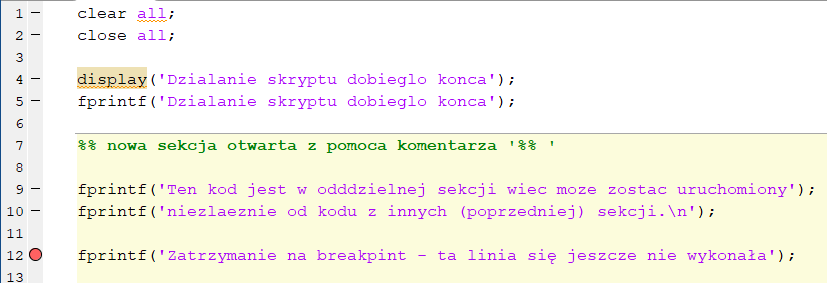

**W tym momencie interpretator poleceń jest w trybie debugowania i MATLAB może się zachowywać tak, jakby się zawiesił. Interpretator poleceń zatrzymał swoją normalną pracę, co sygnalizuje w konsoli specjalnym znakiem zachęty "K>>":**

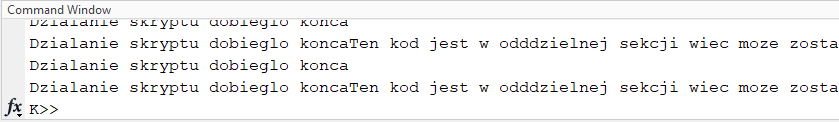

Dopóki interpretacja komend nie zostanie zakończona, MATLAB nie reaguje na kontrolki interfejsu użytkownika. W chwili zatrzymania za pomocą konsoli mamy dostęp do pamięci (przestrzeni danych) widzianej z miejsca zatrzymania i możemy, również za pomocą konsoli, wykonywać na tej pamięci dowolne operacje. Przykładowo możemy wypisać wartość zmiennych na konsolę, albo wywoływać funkcje.

Możemy też wykonywać kod krok po kroku przy pomocy kontrolek 'Step' i 'Step In' (odpowiednio F10 i F11).

Aby zakończyć debugowanie możemy:

- kliknąć kontrolkę 'Stop',

- wpisać w konsolę komendę 'return'.

**UWAGA! MATLAB kolejkuje żądania dla interpretera. Dlatego m.in. w przypadku zatrzymania w breakpoincie, albo np. nieskończonej pętli klikanie kontrolki 'RUN' może powodować zakolejkowanie dużej ilości żądań. Wykonują się one natychmiast po obsłużeniu bieżącego żądania, czasami wydawać się zatem może, jakby MATLAB wisiał. Powrócimy do tego tematu przy okazji pętli.**

Warszawa, 27.02.2021 r.                                                                                                           **© **K. Król

Sem. 21L